clear; clc;
m = 0.8;
g = 9.81;
l = 1.5;
tau = 0.2;
% syms m g l tau
syms theta(t);
ode = m*(l^2)*diff(theta, t, 2) - tau + m*g*l*cos(theta) == 0;
% 
% % define initial conditions
% Dy = diff(theta,t,1);
% cond1 = theta(0) == 0;
% cond2 = Dy(0) == 0;
% conds = [cond1 cond2];
% 
% %solve ode
% dsolve(ode, conds, "Implicit", true)

% solve ode numerically
[V] = odeToVectorField(ode)

$$V = \left(\begin{array}{c} Y_{2}\\ \frac{1}{9}-\frac{327\,\cos\left(Y_{1}\right)}{50} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);cos(Y(1)).*(-3.27e+2./5.0e+1)+1.0./9.0]


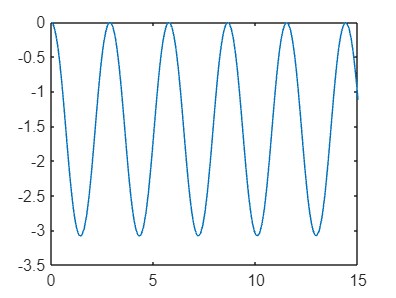

[t, y] = ode45(M,[0 15], [0 0]);
out_1_dof = y(:,1);
plot(t, out_1_dof)